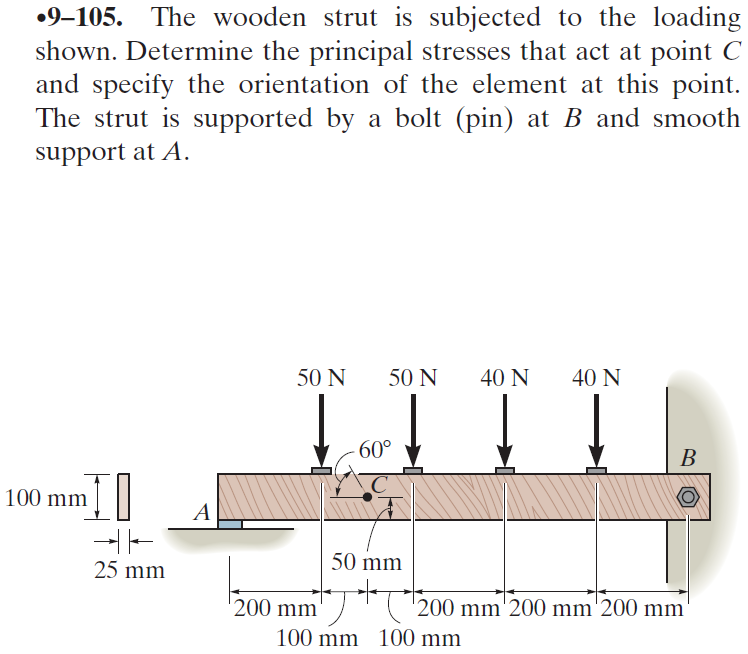

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-105RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-105RP-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('concentrated', 'force', -50*u.N, 200*u.mm);
b = b.add('concentrated', 'force', -50*u.N, 400*u.mm);
b = b.add('concentrated', 'force', -40*u.N, 600*u.mm);
b = b.add('concentrated', 'force', -40*u.N, 800*u.mm);
b = b.add('reaction', 'force', 'Rb', 1000*u.mm);
b.L = 1000*u.mm;

# section properties

B = 25*u.mm;
H = 100*u.mm;
b.I = B*H^3/12;
A = B*H;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(27360000\,{\mathrm{mm}}^{2}-47\,x^{2}\right)}{6250000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }x\leq 200\,\mathrm{mm}\\ \frac{11\,x^{3}+7500\,x^{2}\,\mathrm{mm}-15180000\,x\,{\mathrm{mm}}^{2}+100000000\,{\mathrm{mm}}^{3}}{3125000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }x\in \left(200\,\mathrm{mm},400\,\mathrm{mm}\right]\\ -\frac{3\,\left(x^{3}-15000\,x^{2}\,\mathrm{mm}+14120000\,x\,{\mathrm{mm}}^{2}-600000000\,{\mathrm{mm}}^{3}\right)}{6250000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }x\in \left(400\,\mathrm{mm},600\,\mathrm{mm}\right]\\ -\frac{23\,x^{3}-81000\,x^{2}\,\mathrm{mm}+63960000\,x\,{\mathrm{mm}}^{2}-6120000000\,{\mathrm{mm}}^{3}}{6250000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }x\in \left(600\,\mathrm{mm},800\,\mathrm{mm}\right]\\ -\frac{\left(x-1000\,\mathrm{mm}\right)\,\left(43\,x^{2}-86000\,x\,\mathrm{mm}+16360000\,{\mathrm{mm}}^{2}\right)}{6250000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }800\,\mathrm{mm}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{3\,\left(9120000\,{\mathrm{mm}}^{2}-47\,x^{2}\right)}{6250000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }x\leq 200\,\mathrm{mm}\\ \frac{3\,\left(11\,x^{2}+5000\,x\,\mathrm{mm}-5060000\,{\mathrm{mm}}^{2}\right)}{3125000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }x\in \left(200\,\mathrm{mm},400\,\mathrm{mm}\right]\\ -\frac{3\,\left(3\,x^{2}-30000\,x\,\mathrm{mm}+14120000\,{\mathrm{mm}}^{2}\right)}{6250000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }x\in \left(400\,\mathrm{mm},600\,\mathrm{mm}\right]\\ -\frac{3\,\left(23\,x^{2}-54000\,x\,\mathrm{mm}+21320000\,{\mathrm{mm}}^{2}\right)}{6250000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }x\in \left(600\,\mathrm{mm},800\,\mathrm{mm}\right]\\ -\frac{3\,\left(43\,x^{2}-86000\,x\,\mathrm{mm}+34120000\,{\mathrm{mm}}^{2}\right)}{6250000\,\text{E}}\,\frac{N}{{\mathrm{mm}}^{4}} & \text{ if }800\,\mathrm{mm}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 94\,x\,N & \text{ if }x\leq 200\,\mathrm{mm}\\ 4\,\left(11\,x+2500\,\mathrm{mm}\right)\,N & \text{ if }x\in \left(200\,\mathrm{mm},400\,\mathrm{mm}\right]\\ -6\,\left(x-5000\,\mathrm{mm}\right)\,N & \text{ if }x\in \left(400\,\mathrm{mm},600\,\mathrm{mm}\right]\\ -2\,\left(23\,x-27000\,\mathrm{mm}\right)\,N & \text{ if }x\in \left(600\,\mathrm{mm},800\,\mathrm{mm}\right]\\ -86\,\left(x-1000\,\mathrm{mm}\right)\,N & \text{ if }800\,\mathrm{mm}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 94\,N & \text{ if }x\leq 200\,\mathrm{mm}\\ 44\,N & \text{ if }x\in \left(200\,\mathrm{mm},400\,\mathrm{mm}\right]\\ -6\,N & \text{ if }x\in \left(400\,\mathrm{mm},600\,\mathrm{mm}\right]\\ -46\,N & \text{ if }x\in \left(600\,\mathrm{mm},800\,\mathrm{mm}\right]\\ -86\,N & \text{ if }800\,\mathrm{mm}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 94\,N\\ \mathrm{Rb} & 86\,N \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

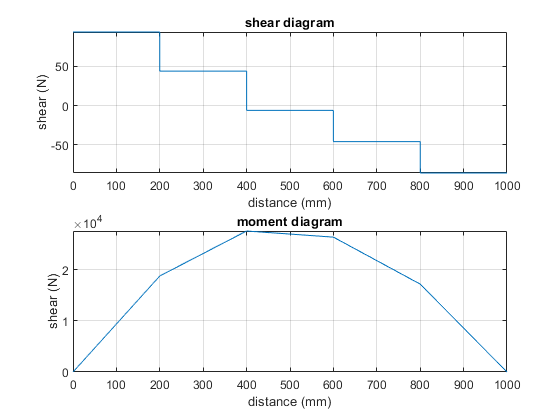

beam.shear_moment(m, v, [0 b.L], {'N' 'mm'});

# loads at point C

M = m(300*u.mm)

$$M = 23200\,N\,\mathrm{mm}$$

V = v(300*u.mm)

$$V = 44\,N$$

# stresses at point C

sigma_bending = sym(0)

$$sigma\_bending = 0$$

tau_shear = rewrite(-3*V/(2*A), u.kPa);
tau_shear_vpa = vpa(tau_shear) %#ok<NASGU> 

$$tau\_shear\_vpa = -26.4\,\mathrm{kPa}$$

# mohr stresses at point C

sigmax = sigma_bending

$$sigmax = 0$$

sigmay = sym(0)

$$sigmay = 0$$

tauxy = tau_shear;
tauxy_vpa = vpa(tauxy)

$$tauxy\_vpa = -26.4\,\mathrm{kPa}$$

[sigmaxp sigmayp tauxyp thetap] = beam.principal(sigmax, sigmay, tauxy);
[sigmaxs sigmays tauxys thetas] = beam.max_shear(sigmax, sigmay, tauxy);

# mohr's circle for point C

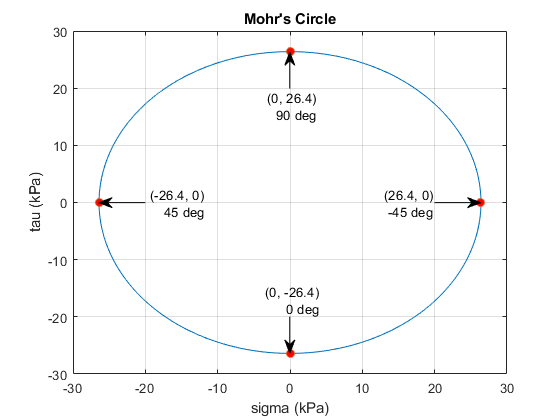

beam.mohr_plot(sigmax, sigmay, tauxy, {'kPa'});
axis([-30 30 -30 30]);
xvals = double(separateUnits([sigmaxp sigmaxs]));
yvals = double(separateUnits([tauxyp tauxys]));
thetavals = double(separateUnits([thetap thetas]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = 20;
      y1 = 0;
    case 2
      x1 = -20;
      y1 = 0;
    case 3
      x1 = 0;
      y1 = -20;
    case 4
      x1 = 0;
      y1 = 20;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear old_assum;
clear tau_shear_vpa;
clear xvals yvals thetavals k x1 y1 x2 y2 text_str;